CDo = 0.0253;

CLCDMax = 0;

for i = 1:211
    
    AoA(i) = -21.1+i*0.1;
    
    [CL(i),CD(i)] = Vanguard_VLM(AoA(i));
    
    if CL(i)/(CD(i)+CDo) > CLCDMax
        
        CLCDMax = CL(i)/(CD(i)+CDo);
        
    end
    
end

CLCDMax

CLCDMax = 13.9670

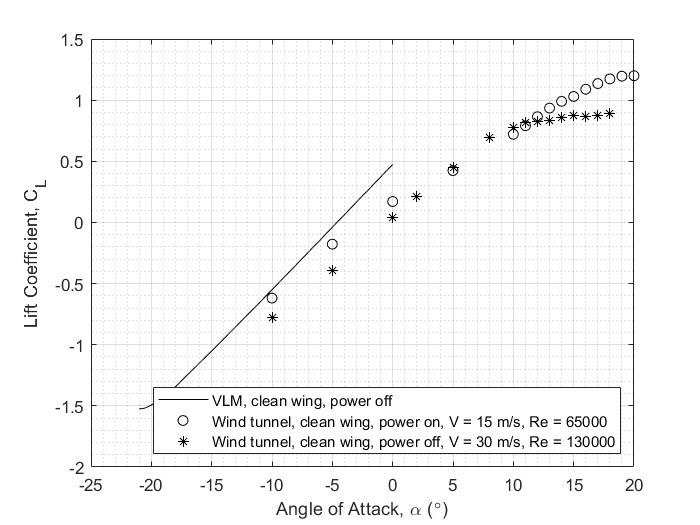


figure
plot(AoA,CL,'black')
hold on
scatter(AoA1,CL1,'black','Marker','o')
scatter(AoA2,CL2,'black','Marker','*')
hold off
grid on
grid minor
xlabel('Angle of Attack, \alpha ({\circ})')
ylabel('Lift Coefficient, C_L')
legend('VLM, clean wing, power off','Wind tunnel, clean wing, power on, V = 15 m/s, Re = 65000','Wind tunnel, clean wing, power off, V = 30 m/s, Re = 130000', 'Location','southeast')

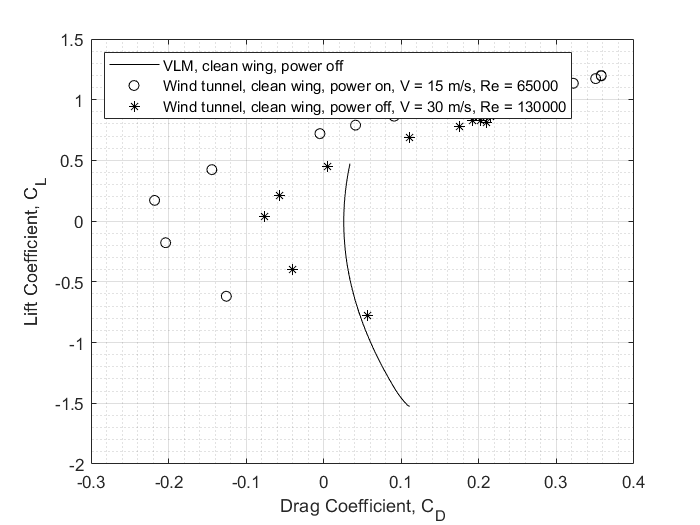


figure
plot(CD+CDo,CL, 'black')
hold on
scatter(CD1,CL1,'black','Marker','o')
scatter(CD2,CL2,'black','Marker','*')
hold off
grid on
grid minor
xlabel('Drag Coefficient, C_D')
ylabel('Lift Coefficient, C_L')
legend('VLM, clean wing, power off','Wind tunnel, clean wing, power on, V = 15 m/s, Re = 65000','Wind tunnel, clean wing, power off, V = 30 m/s, Re = 130000', 'Location','northwest')